% Load MRST modules
mrstModule add ad-core ad-blackoil ad-props

% Define grid and rock properties
nx = 50; ny = 50; nz = 10;
G = cartGrid([nx, ny, nz], [500, 500, 50]);  % Grid with dimensions 500x500x50 meters
G = computeGeometry(G);

% Define rock properties
rock.poro = repmat(0.1, [G.cells.num, 1]); % Porosity
rock.perm = repmat(1 * milli * darcy, [G.cells.num, 1]); % Permeability

% Initialize fluid properties
fluid = initSimpleADIFluid('phases', 'WOG', ...
                           'mu', [0.3, 0.8, 0.05] .* centi * poise, ... % Viscosities of water, oil, gas
                           'rho', [1000, 800, 500] .* kilogram/meter^3, ... % Densities of water, oil, gas
                           'n', [2, 2, 2]); % Corey exponents

% Define initial state
initial_pressure = 200 * barsa; % Initial pressure
initial_saturation = [0.1, 0.1, 0.8]; % Initial saturations for water, oil, gas
state = initResSol(G, initial_pressure, initial_saturation);

% Define wells (one injector for CO2)
W = addWell([], G, rock, 1, 'Type', 'bhp', 'Val', 300 * barsa, ...
            'Radius', 0.1, 'Comp_i', [0, 0, 1]); % CO2 injector

% Set up the simulation model
model = GenericBlackOilModel(G, rock, fluid);

% Define schedule (injection of CO2)
injection_time = 5 * year; % Total simulation time

dt = rampupTimesteps(injection_time, 30*day, 8);
schedule = simpleSchedule(dt, 'W', W);

% Run the simulation
[wellSols, states] = simulateScheduleAD(state, model, schedule);

Solving timestep 01/69:         -> 2 Hours, 2925 Seconds
Solving timestep 02/69: 2 Hours, 2925 Seconds -> 5 Hours, 2250 Seconds
Solving timestep 03/69: 5 Hours, 2250 Seconds -> 11 Hours, 900 Seconds
Solving timestep 04/69: 11 Hours, 900 Seconds -> 22 Hours, 1800 Seconds
Solving timestep 05/69: 22 Hours, 1800 Seconds -> 1 Day, 21 Hours
Solving timestep 06/69: 1 Day, 21 Hours -> 3 Days, 18 Hours
Solving timestep 07/69: 3 Days, 18 Hours -> 7 Days, 12 Hours
Solving timestep 08/69: 7 Days, 12 Hours -> 15 Days
Solving timestep 09/69: 15 Days -> 30 Days
Solving timestep 10/69: 30 Days -> 60 Days
Solving timestep 11/69: 60 Days -> 90 Days
Solving timestep 12/69: 90 Days -> 120 Days
Solving timestep 13/69: 120 Days -> 150 Days
Solving timestep 14/69: 150 Days -> 180 Days
Solving timestep 15/69: 180 Days -> 210 Days
Solving timestep 16/69: 210 Days -> 240 Days
Solving timestep 17/69: 240 Days -> 270 Days
Solving timestep 18/69: 270 Days -> 300 Days
Solving timestep 19/69: 300 Days -> 330 Days
So

%% Plot plume at end of simulation.
sat_end = states{end}.s(:,2);  % co2 saturation at end state
 
% Plot cells with CO2 saturation more than 0.05
plume_cells = sat_end >  0.05;

clf; plotGrid(G,'facecolor', 'yellow');  %plot outline of simulation grid
plotGrid(G, plume_cells, 'facecolor', 'red');%plot cells with CO2 in red
plotWell (G, W, 'fontsize', 12 , 'color' , 'k');
view(35, 35);
% Post-process and visualize results
figure;
plotToolbar(G, states);
title('CO2 Sequestration in Shale Reservoir');

% Display the final state of the reservoir
final_state = states{end};
plotCellData(G, final_state.s(:,3)); % Plot the gas saturation
colorbar;
title('Final CO2 Saturation');

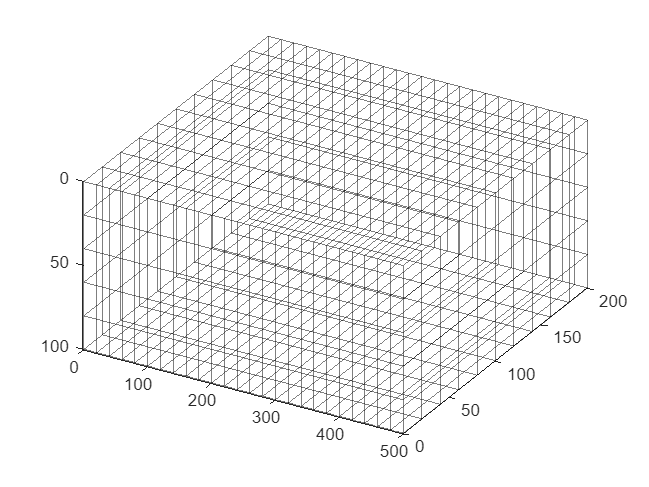

% Load necessary modules
mrstModule add hfm;             % hybrid fracture module
mrstModule add mrst-gui;        % plotting routines
mrstModule add compositional;   % replace ad-blackoil with compositional module
mrstModule add ad-core;         % AD core module
mrstModule add ad-props;        % AD properties
mrstModule add co2lab;
%% Set up a matrix grid
% We first set up a Cartesian matrix grid with dimensions 500m x 200m x
% 100m with grid blocks that are 10m x 10m x 10m. Matrix permeability is
% 100mD and porosity is 30%.

celldim = [25, 10, 5];
physdim = [500, 200, 100];
G = cartGrid(celldim, physdim); 
G = computeGeometry(G);
G.rock=makeRock(G,100*milli*darcy,0.3);

%plot Matrix Grid
figure;
plotGrid(G,'facealpha',0,'edgealpha',.5);
view(30,45);

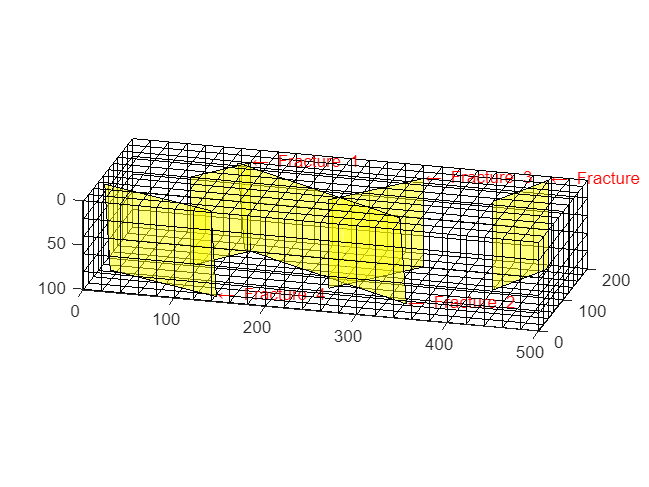

%% Set up fracture planes
% Fracture planes are set up by defining their vertices. Additionally,
% the aperture, porosity and permeability of the fractures are provided.
% Fracture planes 1 and 3 will be vertical while fracture 2 is slanted.

% Fracture plane 1
fracplanes(1).points = [90 100 0;
                        140 160 0;
                        140 160 100;
                        90 100 100];
fracplanes(1).aperture = 1/25;
fracplanes(1).poro=0.8;
fracplanes(1).perm=10000*darcy;

% Fracture plane 2 
points = [130 160 0
          340 40 0
          340 40 100
          130 160 100];

f2normal = getnormal(points);
points([1,2],:)=points([1,2],:)+f2normal*5; % displace top points
points([3,4],:)=points([3,4],:)-f2normal*5; % displace bottom points

fracplanes(2).points = points;
fracplanes(2).aperture = 1/25;
fracplanes(2).poro=0.8;
fracplanes(2).perm=10000*darcy;

% Fracture plane 3
fracplanes(3).points = [250 70 0
                        330 160 0
                        330 160 100
                        250 70 100];
fracplanes(3).aperture = 1/25;
fracplanes(3).poro=0.8;
fracplanes(3).perm=10000*darcy;

% Fracture plane 4 
points = [10 60 0
          140 10 0
          140 10 100
          10 60 100];

f4normal = getnormal(points);
points([1,2],:)=points([1,2],:)+f4normal*5; % displace top points
points([3,4],:)=points([3,4],:)-f4normal*5; % displace bottom points

fracplanes(4).points = points;
fracplanes(4).aperture = 1/25;
fracplanes(4).poro=0.8;
fracplanes(4).perm=10000*darcy;

% Fracture plane 5
fracplanes(5).points = [420 110 0
                        460 190 0
                        460 190 100
                        420 110 100];

fracplanes(5).aperture = 1/25;
fracplanes(5).poro=0.8;
fracplanes(5).perm=10000*darcy;

% Plot fracture planes
figure;
plotfracongrid(G,fracplanes); % visualize to check before pre-processview(30,45)

%% Construct fracture grid
% The fracture grid is constructed using the matrix grid. The matrix grid
% will serve as a 'cookie cutter' to subdivide the fracture planes.
% Parallel processing can be used to speed up this process (Start a 
% parallel pool to do this).

tol=1e-5;
[G,fracplanes]=EDFMgrid(G,fracplanes,...
    'Tolerance',tol,'fracturelist',1:5);

Processing 1 out of 5 fractures.
Processing 2 out of 5 fractures.
Processing 3 out of 5 fractures.
Processing 4 out of 5 fractures.
Processing 5 out of 5 fractures.
EDFM grid assembly took 1.3081 seconds.

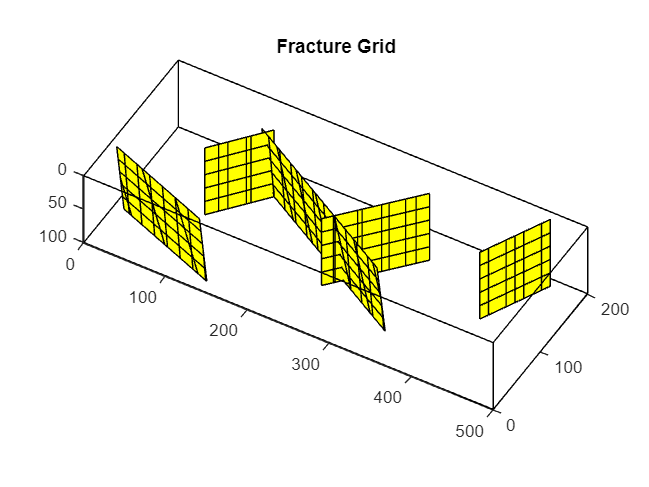

% Plot Fracture grid
figure;
plotGrid(cartGrid([1 1 1],physdim),'facealpha',0);
hold on;
plotGrid(G,G.Matrix.cells.num+1:G.cells.num);
axis tight equal
title('Fracture Grid')
view(30,45);

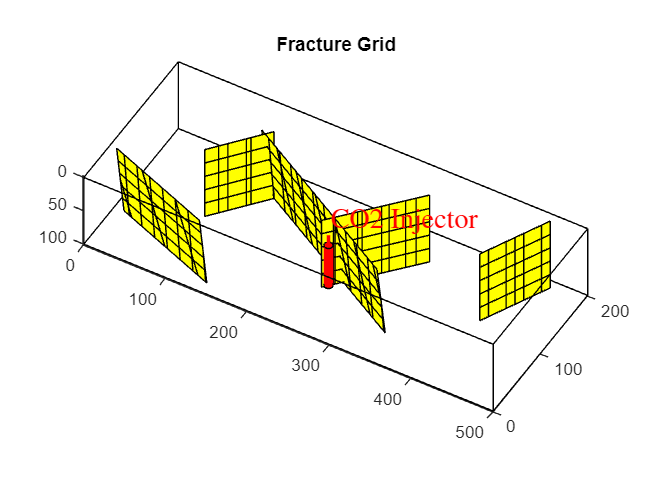

gravity reset off
g = gravity;
%% Setup initial state in the aquifer.
rho_wat = 1000; % density of brine in kg/m3
initState.pressure = rho_wat * g(3) * G.cells.centroids(:,3);
initState.s = repmat([1,0], G.cells.num, 1); % [initial water and CO2 saturations]
initState.sGmax = initState.s(:,2); % historically maximum CO2 saturation

%% Fluid model.
% Load sampled tables of co2 fluid properties
co2 = CO2props();

% Reference pressure (Bar) and temperature (f)
p_ref   = 15 * mega * Pascal;
t_ref   = 70 + 273.15;

% CO2 viscosity and density at reference pressure and temperature, and CO2 compressibility
mu_co2 = co2.mu(p_ref, t_ref) * Pascal * second;
rho_co2 = co2.rho(p_ref, t_ref);
cf_co2  = co2.rhoDP(p_ref, t_ref) / rho_co2;

% Brine viscosity and compressibility
mu_wat = 8e-4 * Pascal * second;
cf_wat  = 0;

% Rock compressibility
cf_rock = 4.35e-5 / barsa;

% Fluid object that contains the fluid properties such as density, viscosity, and relative permeability curves
fluid = initSimpleADIFluid('phases', 'WG'           , ...
                           'mu'  , [mu_wat, mu_co2]     , ...
                           'rho' , [rho_wat, rho_co2]     , ...
                           'pRef', p_ref            , ...
                           'c'   , [cf_wat, cf_co2] , ...
                           'cR'  , cf_rock          , ...
                           'n'   , [2 2]); % monomials describing relative permeability for each phase

%% CO2 injection well.
% Injection rate in m3/s - Inject 0.85 Million tonnes per year
inj_rate = 3.75 * mega * 1e3 / year / fluid.rhoGS; % fluid.rhoGS is the density of CO2 at reference temperature

wellRadius = .75;
[nx, ny, nz] = deal(G.cartDims(1), G.cartDims(2), G.cartDims(3));

% Injector
cellinj = 64:nx*ny:(1+(nz-1)*nx*ny);


%cellprod = nx*ny:nx*ny:nz*nx*ny;

W   = addWell([], G, G.rock,cellinj, ...
    'InnerProduct', 'ip_tpf', 'Type', 'rate', 'Val', inj_rate, ...
    'Radius', wellRadius, 'Comp_i', [0, 1], 'Name', 'CO2 Injector', 'Sign', 1);% CO2 injection


hold on;
plotWell(G,W);

%% Two phase water gas model.
% class twoPhaseGasWaterModel(G, rock, fluid, tsurf, tgrad, varargin)
model = TwoPhaseWaterGasModel(G, G.rock, fluid, 0, 0);

Tinjection = 140*year;
% Create time steps that ramp up geometrically- The function takes three input arguments: Tmax which is the total simulation time, dtmin which is the smallest time step and nsteps which is the number of time steps. In this case two years injection with increasing timestep size.
%dT = rampupTimesteps(Tinjection,year/12,1);  

dt = rampupTimesteps(Tinjection, 180*day, 2);
%dt=dt(1:75);
schedule = simpleSchedule (dt, 'W', W);
[wellSol, states] = simulateScheduleAD(initState, model, schedule);%% Plot plume at end of simulation.

Solving timestep 001/287:           -> 45 Days


Solver failure after 7 iterations for timestep of length 45 Days. Cutting timestep.
Failure reason: Linear solver failure: : Linear system rhs must have finite entries.
Cutting timestep.


Solver did not converge in 25 iterations for timestep of length 22 Days, 12 Hours. Cutting timestep.


Solver did not converge in 25 iterations for timestep of length 11 Days, 6 Hours. Cutting timestep.


Solver did not converge in 25 iterations for timestep of length 5 Days, 15 Hours. Cutting timestep.


Solving timestep 002/287: 45 Days   -> 90 Days
Solving timestep 003/287: 90 Days   -> 180 Days
Solving timestep 004/287: 180 Days  -> 360 Days
Solving timestep 005/287: 360 Days  -> 1 Year, 174 Days, 18.18 Hours
Solving timestep 006/287: 1 Year, 174 Days, 18.18 Hours -> 1 Year, 354 Days, 18.18 Hours
Solving timestep 007/287: 1 Year, 354 Days, 18.18 Hours -> 2 Years, 169 Days, 12.36 Hours
Solving timestep 008/287: 2 Years, 169 Days, 12.36 Hours -> 2 Years, 349 Days, 12.36 Hours
Solving timestep 009/287: 2 Years, 349 Days, 12.36 Hours -> 3 Years, 164 Days, 6.54 Hours
Solving timestep 010/287: 3 Years, 164 Days, 6.54 Hours -> 3 Years, 344 Days, 6.54 Hours
Solving timestep 011/287: 3 Years, 344 Days, 6.54 Hours -> 4 Years, 159 Days, 2592.00 Seconds
Solving timestep 012/287: 4 Years, 159 Days, 2592.00 Seconds -> 4 Years, 339 Days, 2592.00 Seconds
Solving timestep 013/287: 4 Years, 339 Days, 2592.00 Seconds -> 5 Years, 153 Days, 18.90 Hours
Solving timestep 014/287: 5 Years, 153 Days, 18.90 

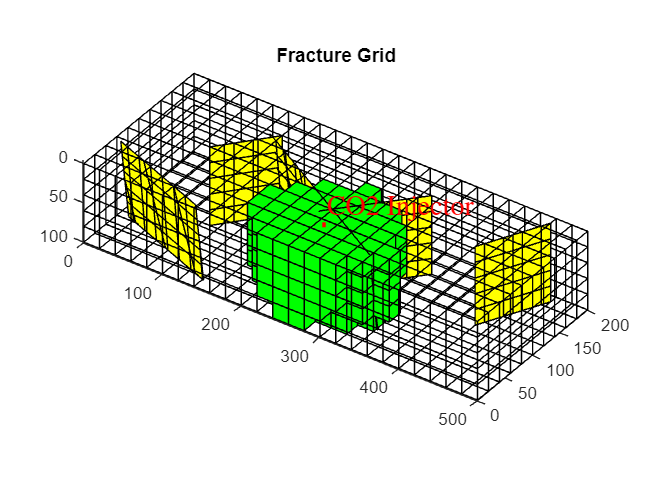

sat_end = states{end}.s(:,2);  % co2 saturation at end state

% Plot cells with CO2 saturation more than 0.05
plume_cells = sat_end > 0.05;

hold on; plotGrid(G, 'facecolor', 'none');  % plot outline of simulation grid
plotGrid(G, plume_cells, 'facecolor', 'green'); % plot cells with CO2 in red
view(35, 35);

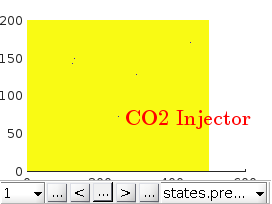

%% Inspect results interactively using plotToolbar.
clf;
plotToolbar(G, states)
plotWell(G,W)